# `Vehicle Acceleration Simulations`

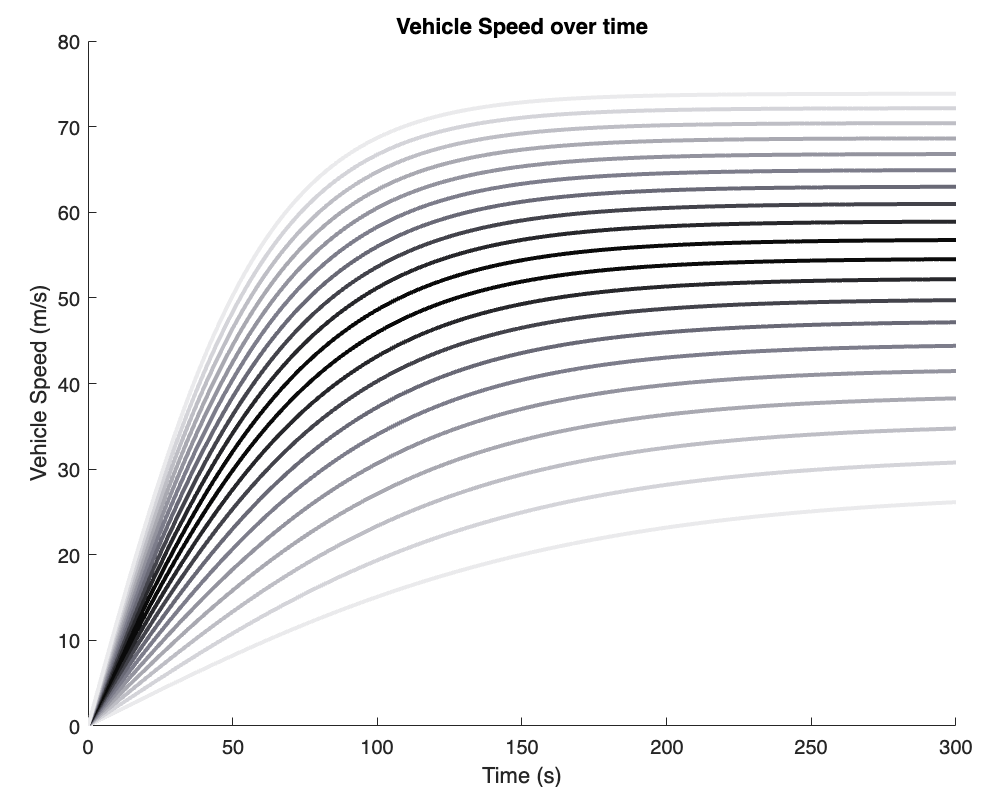

`Check out the Equations of motion, Matlab Script, Simulink, and more at my github repository`

[`https://github.com/BrianLesko/LongitudinalVehicleDynamics`](https://github.com/BrianLesko/LongitudinalVehicleDynamics)

`Longitudinal Vehicle Modeling Series`

`7/24/23`

`Brian Lesko, Graduate Researcher and Teaching Associate, Masters of mechanical engineering student `

` Ohio State University`

clc; clear; close all;
Vstart = 0;

# Acceleration Simulations

### Running and recording simulation data

In this simulation set, the vehicle accelerates until it reaches a steady state. 20 simulations each using a different constant motor torque. No wind or road slope. 

% unchanging Sim parameters for pure acceleration
[motorStart,motorStartTime,motorIncrease,motorIncreaseTime,motorDecrease,motorDecreaseTime,brakeTime,breakStrength,headWindTime,headWind,roadSlopeTime,roadSlope] = setLongitudinalInputsToZero();
[M, eta_t, lambda_t, lambda_f, I_w, R_w, Meq, C_d, rho, A_f, g, C_rr, C_x, C_alpha,L, l_f, l_r, C_s, I_z, mu] = getLogitudinalParameters();

n=20;
for i = 1:1:n
    
    increment = 10;
    motorStart = i*increment + 40;

    % Create a Sim Name
    ID = ['pureAcceleration_', num2str(i)]; % this is a cell, which contains text
    sim('long_model72423')
    simResult = shortenAndTableSimVariables(Xout,Yout,ID); % save sim results as a table

    % We use cells to create n new tables
    vehicleCellsAcceleration{i} = simResult;
    varDescriptions = {'vehicle ID','time (s)', 'motor torque (Nm)', 'brake torque (Nm)','position (m)','velocity (m/s)','acceleration (m/s^2)','headwind (N)','road slope (deg)','friction coefficient'};
    vehicleCellsAcceleration{i}.Properties.VariableDescriptions = varDescriptions;
end
accelerationSims = vertcat(vehicleCellsAcceleration{:,1},vehicleCellsAcceleration{:,2},vehicleCellsAcceleration{:,3},vehicleCellsAcceleration{:,4})

accelerationSims = 2400×10 table
          IDvec              time       Tm    Tb        X            V            A         wind    slope    mu 
    __________________    __________    __    __    __________    ________    __________    ____    _____    ___

    pureAcceleration_1             0    50    0              0        0.01        3.2846     0        0      0.7
    pureAcceleration_1    0.00096324    50    0     1.0842e-05    0.011765      -0.10895     0        0      0.7
    pureAcceleration_1     0.0010892    50    0     1.2325e-05    0.011787      -0.10909     0        0      0.7
    pureAcceleration_1      0.001194    50    0     1.3561e-0

## Velocity Time Curves 

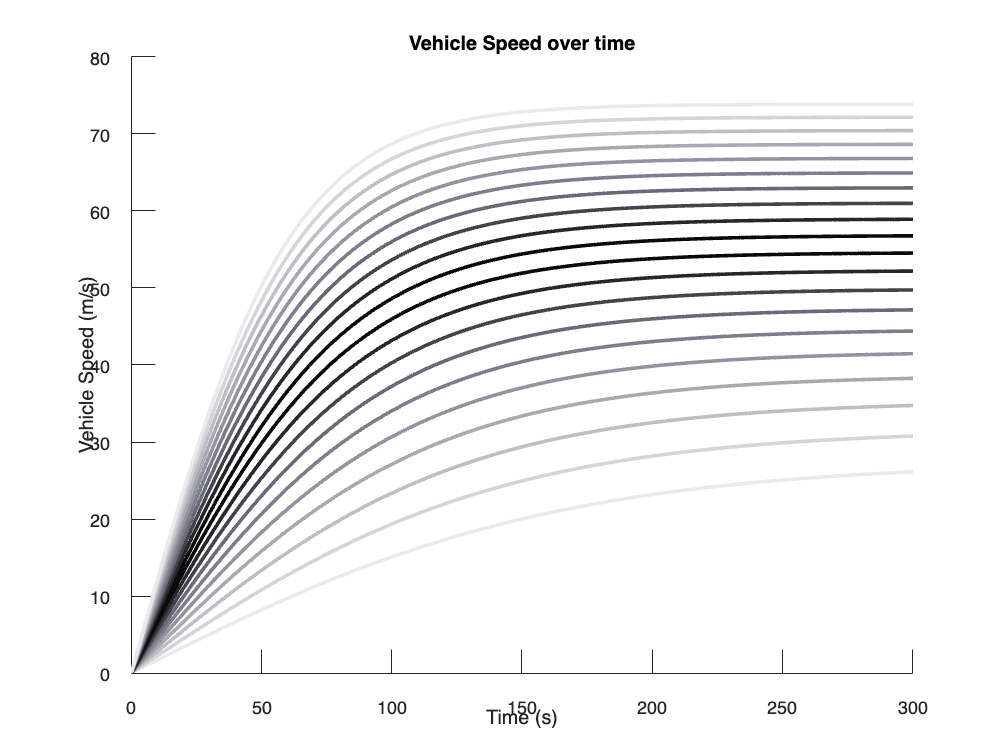

close all, figure
legendInfo = plotSimCellsV_t4(vehicleCellsAcceleration);

# Model Used

## `Wheel Equations of Motion`

`The equations of motion of a system are derived after creating the relevant free body diagrams. On each body, the forces and torques are summed for use with Newtons Second Law, F=ma or T=Ia.`

`The wheel's equations of motion are as follows: `

`The Sum of forces in the X yeilds: `

`M x'' = Fr + Fgr - Faero - Frr`

`where Fgr and Frr are the components of the vehicle's weight force.`

`Sum of moments (clockwise positive)`

`Iw theta''  = Tdrive - Tbrake - (Rw * Froad) - Fgr`

`where Rw is the wheel radius`

## `Component Equations`

`Driveshaft Torque (Td, Tdrive):     Td = Tmotor * Ng `

`Road Force (Fr, Froad):       Fr = Cx * slip`

`slip:             slip   = (theta' * Rw - x') / MAX(x' , theta' * Rw , 1e-7)`

`Drag Force (Fa,Faero):  Fa = (x' + wind force)^2 * air density * Cd * Vehicle Frontal Area * 1 / 2 wheels`

`Vertical Load Components `

`    Rolling Resistance      Frr = cos(road slope) * Crr * M*g`

`    Grade           Fgr = sin(road slope) * M*g`

## `Variables `

`Text variables, CSV format`

`Variable,Description,Units`

`k,Driveshaft stiffness constant,Nm/rad`

`Ng,Gear ratio constant (motor speed/wheel speed),None`

`Tmotor,Input,Nm`

`theta_shaft,Shaft state derived from the motor FBD,rad`

`theta,Wheel state,rad`

`Cx,Slip Stiffness,N per slip`

`slip,Fraction of wheel slip,None`

`theta',Wheel state derivative,rad/s`

`Rw,Wheel radius,m`

`x',Wheel state derivative,m/s`

`wind force,Wind force,N`

`air density,Air density,kg/m^3`

`Cd,Drag coefficient,None`

`Vehicle Frontal Area,Vehicle Frontal Area,m^2`

`road slope,Road slope,rad`

`Crr,Rolling resistance coefficient,None`

`M,Vehicle mass,kg`

`g,Gravity,m/s^2`

`Tb - Brake Torque (Nm)`

`Iw - moment of inertia of the wheel `

# `Simulink Model `

`Simulink is a MATLAB-based graphical programming environment for modeling, simulating and analyzing multi-domain dynamic systems. It's useful because it lets engineers design, simulate, and test control systems in a virtual environment before implementing in hardware, decreasing error margin and testing time. It calculates functions, integrals, or differential equations. Blocks represent mathematical or logical functions or physical devices to relate inputs and outputs. Simulink solves these block diagram models as sets of algebraic and differential equations by numeric integration.`

`The powertrain's equations of motion were directly translated into simulink blocks, which together represent the differential equations of motion of the powertrain system detailed in the previous section. The figure below organizes input and output signals. Input signals are taken as given during the simulation and include all the degrees of freedom of the system. For this simulation, there are 5 as follows: Motor torque, Brake torque, Wind force, Road slope, and the road friction coefficient. These signals are packaged into a bus along with the time signal and sent to the variable Xout, accessible in matlab. The simulation block takes these signals and outputs the relevant simulation outputs as follows: wheel spin states of angle theta, angular speed omega, and angular acceleration alpha; wheel translation states of distance, velocity, and acceleration; and the slip ratio; side slip angle; and tire forces Fx and Fy. The simulation occurs within the simulation block.`

#### `Longitudinal Vehicle Model Top Level Diagram `

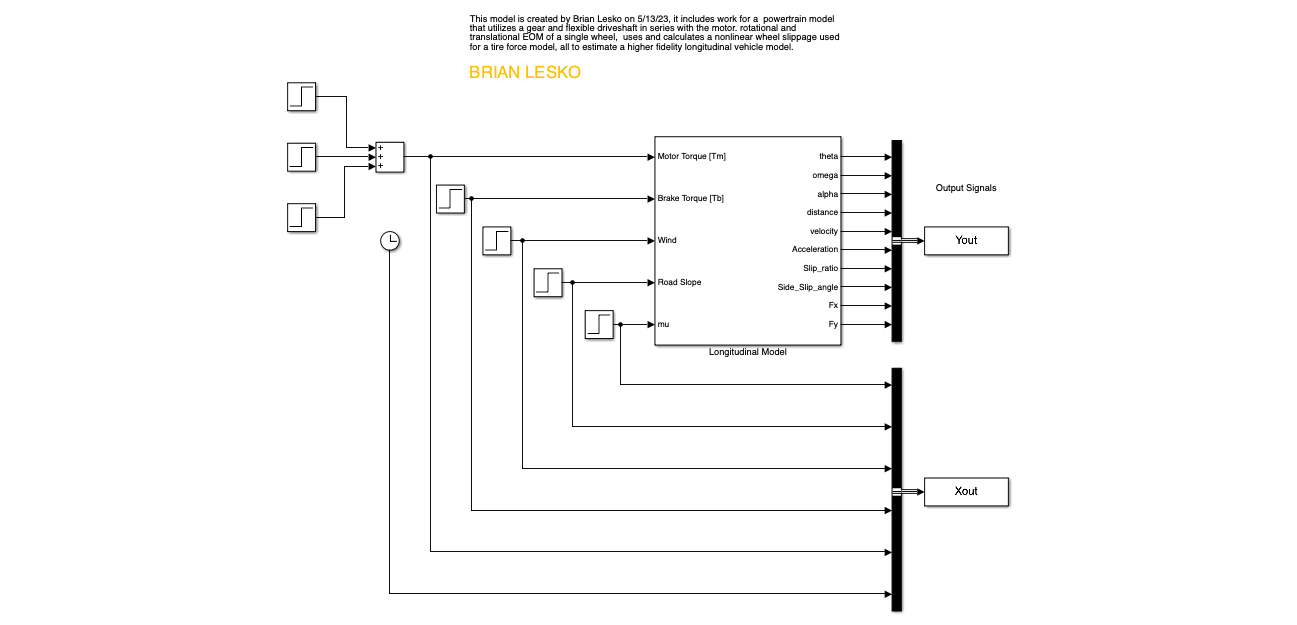

#### `Vehicle Model Diagram, separated by EOM`

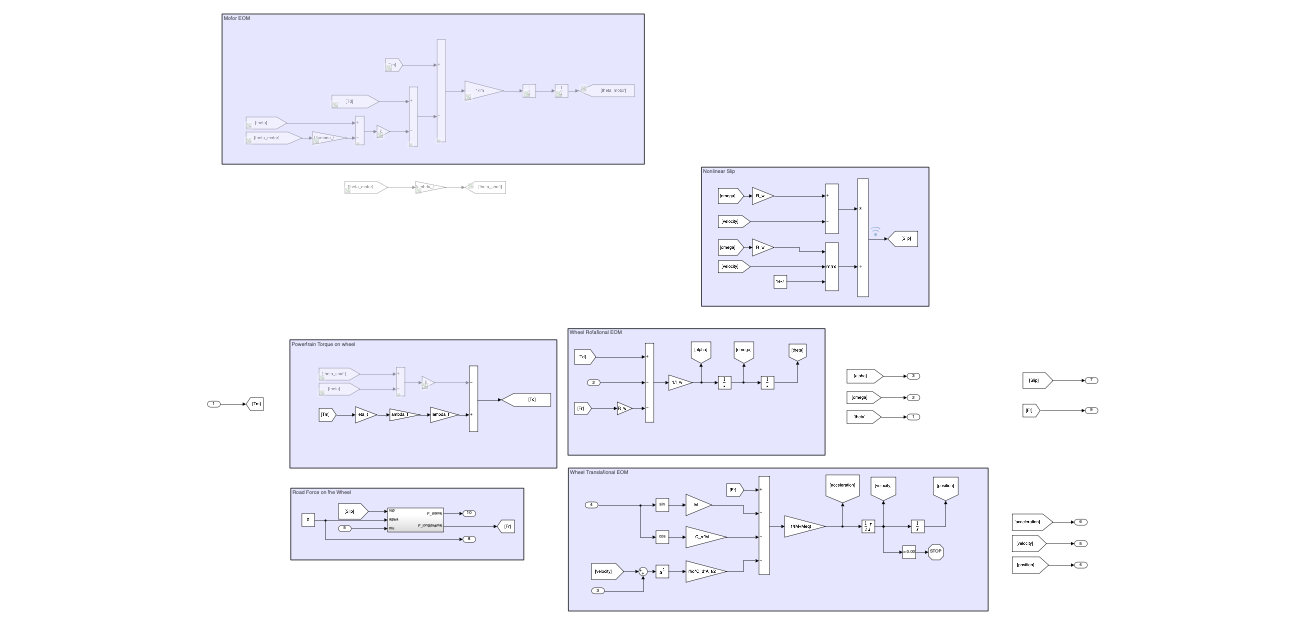

# Functions

function [M, eta_t, lambda_t, lambda_f, I_w, R_w, Meq, C_d, rho, A_f, g, C_rr, C_x, C_alpha,L, l_f, l_r, C_s, I_z, mu] = getLogitudinalParameters()
    M=2000; % Mass of the vehicle[Kg]
    eta_t=0.9; % Transmission Efficiency
    lambda_t=1.0; % Gear Ratio
    lambda_f=4.1; % Final Drive Ratio
    I_w=1.1; % Inertia of the Wheel[kgm2]
    R_w=0.3; % Wheel Radius[m]
    Meq=0.1*M; % Equivalent Mass Factor
    C_d=0.29; % Drag coefficient
    rho=1.225; % Air density[kg/m3]
    A_f=2.8;% Frontal area	[m2]
    g=9.81;% [N/m2]
    C_rr=0.12;%Rolling resistance coefficient Originally .015
    C_x=3e5; %Longitudinal Stiffness[N]
    C_alpha = 1.5e5; % Cornering Stiffness for 1 tire [N/rad]
    L=2.85;% Wheelbase[m]
    l_f=1.3;% Distance from the center of gravity of the vehicle (CG) to the front axle [m]
    l_r=1.55;% Distance from the center of gravity of the vehicle (CG) to the rear axle [m]
    C_s=1.5e5;% Cornering Stiffness of Front and Rear Tires [N/rad]
    I_z=3700;% Inertia moment around z axis J or Iz [kg/m2]
    mu=0.7; % Road friction coefficient
end 

function [motorStart,motorStartTime,motorIncrease,motorIncreaseTime,motorDecrease,motorDecreaseTime,brakeTime,breakStrength,headWindTime,headWind,roadSlopeTime,roadSlope] = setLongitudinalInputsToZero()  
    motorStart = 0; motorStartTime = 0;
    motorIncrease = 0;motorIncreaseTime = 0; 
    motorDecrease = 0;motorDecreaseTime = 0;
    brakeTime = 0;breakStrength = 0;
    headWindTime = 0;headWind = 0;
    roadSlopeTime = 0;roadSlope = 0;
end 


function y = sampVec(x, b)
    % x: input vector
    % b: length of output vector
    
    a = length(x);
    y = linspace(1, a, b)';
    y = round(y);
    y = x(y);
end

function [mu,slope,wind,Tb,Tm,time,theta,omega,alpha,X,V,A,slip,slipAngle,Fx,Fy] = importSimVariables(Xout,Yout)
    
    % Xout
    mu = Xout(:,1); % Road Coefficient of Friction 
    slope = Xout(:,2); % Road slope
    wind = Xout(:,3); %wind force 
    Tb = Xout(:,4); %Brake Torque
    Tm = Xout(:,5); % Motor Torque
    time = Xout(:,6); % time (s)

    %Yout
    theta = Yout(:,1);
    omega = Yout(:,2);
    alpha = Yout(:,3);
    X = Yout(:,4);
    V = Yout(:,5);
    A = Yout(:,6);
    slip = Yout(:,7);
    slipAngle = Yout(:,8);
    Fx = Yout(:,9);
    Fy = Yout(:,10);

end 

function simResult = shortenAndTableSimVariables(Xout,Yout,ID)

    [mu,slope,wind,Tb,Tm,time,theta,omega,alpha,X,V,A,slip,slipAngle,Fx,Fy] = importSimVariables(Xout,Yout);

    b = length(time);

    % reduce samples to length b
    b = round(max(time)*1); % samples per second of sim time

    names = {'IDvec','time','Tm','Tb','X','V','A','wind','slope','mu'};

    time = sampVec(time, b); Tm = sampVec(Tm, b); Tb = sampVec(Tb, b); X = sampVec(X, b); V = sampVec(V, b); A = sampVec(A, b);
    wind = sampVec(wind, b); mu = sampVec(mu, b); slope = sampVec(slope, b);

    IDvec = repmat(ID, b , 1);
    simResult = table(IDvec,time,Tm,Tb,X,V,A,wind,slope,mu, 'VariableNames', names);
end 

function legendInfo = plotSimCellsV_t(simCells)
n = length(simCells(1,:));
colors = getColors();
    for i = 1:1:n
        % fetching the variables 
        time = simCells{i}.time;
        V = simCells{i}.V;
        Tm = simCells{i}.Tm(1); % (1) because the motor torque is constant
        color = colors(i);
        plot(time,V,'r','linewidth',2,'Color',color);
        legendInfo{i} = sprintf('Motor Torque = %s', num2str(Tm));
    end 
end 

# Animation Functions 

function legendInfo = plotSimCellsV_t4(simCells)
    n = length(simCells(1,:));
    colors = getColors();
    figure;
    hold on;

    % Pre-plotting to get the axes limits
    for i = 1:1:n
        time = simCells{i}.time;
        V = simCells{i}.V;
        plot(time,V,'Color',"#FFFFFF");
    end

    % Get the current axes limits
    ax = gca;
    xl = [0 300];
    yl = ax.YLim;

    % Clear the axes
    cla;

    title('Vehicle Speed over time'), xlabel('Time (s)'), ylabel('Vehicle Speed (m/s)')

    % Initialize animated lines
    h = gobjects(1, n);
    for i = 1:1:n
        color = colors(i);
        h(i) = animatedline('Color', color, 'LineWidth', 2);
        ax = gca;
        ax.XLim = xl;
        ax.YLim = yl;
    end

    % Add points to all lines, updating the plot as we go
    for j = 1:length(simCells{1}.time)
        for i = 1:1:n
            time = simCells{i}.time;
            V = simCells{i}.V;
            addpoints(h(i), time(j), V(j));
        end
        if mod(j,3) == 0 % update the plot every n points
            drawnow;
        end
    end

    % Add legend information
    for i = 1:1:n
        Tm = simCells{i}.Tm(1); % (1) because the motor torque is constant
        legendInfo{i} = sprintf('Motor Torque = %s', num2str(Tm));
    end 
    hold off;
end
function colors = getColors()
    a = "#0A0A0A"; % night
    %b = "#131315"; % night 
    %c = "#1D1D20"; % eerie black
    d = "#27272B"; % raisin black
    %e = "#303036"; % jet
    %f = "#3A3A41"; % onyx
    g = "#43434C"; % onyx
    %h = "#565661"; % davy"s gray
    %i = "#60606C"; % dim gray
    j = "#696977"; % dim gray
    %k = "#737382"; % slate gray
    l = "#7D7D8C"; % taupe gray
    m = "#93939F"; % cool gray
    n = "#A9A9B2"; % french gray
    o = "#BEBEC5"; % french gray
    p = "#D4D4D9"; % platinum
    q = "#EAEAEC"; % anti-flash white

    colors = [q,p,o,n,m,l,j,g,d,a,a,d,g,j,l,m,n,o,p,q]; 
end     

function colors = getColors2()
    a = "#F91079"; 
    d = "#F92484"; 
    g = "#FA388F"; 
    j = "#FA4C9A"; 
    l = "#FB60A6"; 
    m = "#FB74B1"; 
    n = "#FB88BC"; 
    o = "#FB9DC7"; 
    p = "#FCB1D2"; 
    q = "#FDC4DD"; 

    colors = [q,p,o,n,m,l,j,g,d,a,a,d,g,j,l,m,n,o,p,q]; 
end  